global P_Dbl_DPKV_start P_Dbl_DPKV_end P_Dbl_KnockHigh_oscil P_Dbl_KnockLow_oscil; 

P_Dbl_DPKV_start=0; % угол начала вывода ИД (-100 и более)
P_Dbl_DPKV_end=70; %угол окончания вывода ИД (до 150)
P_Dbl_KnockHigh_oscil=2.5; %уровень сильной детонации (бар)
P_Dbl_KnockLow_oscil=0.5; %уроень слабой детонации (бар)
P_Dbl_EngCycle_num=15; %номер цикла для графика

if ~exist ("T_Mtrc_ExcelData")
  T_Mtrc_ExcelData=table2array(readtable("pressure_sens.xlsx"));
end

A_Mtrc_DPKV_full=T_Mtrc_ExcelData(1:length(T_Mtrc_ExcelData),1);
T_Mtrc_CylPress_full=T_Mtrc_ExcelData(1:end,2:end);

A_Mtrc_DPKV=SetctorPKV(A_Mtrc_DPKV_full);

clear T_Mtrc_CylPress_flt T_Mtrc_CylPress;
[rows, collums]=size(T_Mtrc_CylPress_full)

rows = 2500

collums = 100

for i=1:collums 
  A_Mtrc_local=T_Mtrc_CylPress_full(1:end,i);
  A_Mtrc_local_flt=sgolayfilt(A_Mtrc_local, 3, 33);
  A_Mtrc_local_flt=SetctorPKV(A_Mtrc_DPKV_full, A_Mtrc_local_flt);
  T_Mtrc_CylPress_flt(:,i)=A_Mtrc_local_flt;
  
  A_Mtrc_local=T_Mtrc_CylPress_full(1:end,i);
  A_Mtrc_local_flt=SetctorPKV(A_Mtrc_DPKV_full, A_Mtrc_local);
  T_Mtrc_CylPress(:,i)=A_Mtrc_local_flt;
end
 
T_Mtrc_CylPress_oscil=T_Mtrc_CylPress-T_Mtrc_CylPress_flt;
A_Mtrc_Knock_amp=max(T_Mtrc_CylPress_oscil)-min(T_Mtrc_CylPress_oscil);

%сильнейшая детонация:
p_Dbl_Knock_max=max(A_Mtrc_Knock_amp)

p_Dbl_Knock_max = 4.7028

p_Dbl_KnockCycle_num=find(A_Mtrc_Knock_amp==p_Dbl_Knock_max)

p_Dbl_KnockCycle_num = 15

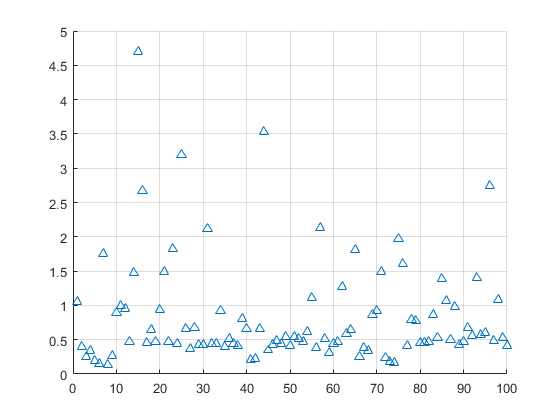


figure(1); hold on; plot(linspace(1,length(A_Mtrc_Knock_amp)),A_Mtrc_Knock_amp, "LineStyle", "none", "Marker", "^")
grid on; hold off;


p_Dbl_KnockHigh_cnt=arrayfun(@HighKnock, A_Mtrc_Knock_amp, 'UniformOutput', false);
Вp_Dbl_KnockHigh_cnt=sum(cell2mat(p_Dbl_KnockHigh_cnt))

p_Dbl_KnockHigh_cnt = 5

p_Dbl_KnockLow_cnt=arrayfun(@LowKnock, A_Mtrc_Knock_amp, 'UniformOutput', false);
p_Dbl_KnockLow_cnt=sum(cell2mat(p_Dbl_KnockLow_cnt))

p_Dbl_KnockLow_cnt = 48

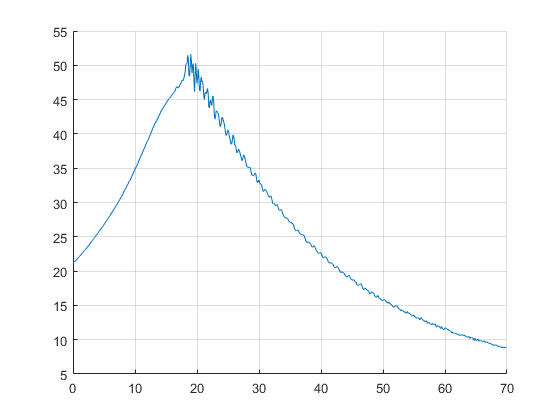


A_Mtrc_CylPress_i=T_Mtrc_CylPress(1:end,P_Dbl_EngCycle_num);

figure(2); hold on; plot(A_Mtrc_DPKV, A_Mtrc_CylPress_i)
grid on; hold off;

function result=HighKnock(x)
global P_Dbl_KnockHigh_oscil;
 if x>= P_Dbl_KnockHigh_oscil
   result=1;
 else result=0;
 end
end

function result=LowKnock(x)
global P_Dbl_KnockHigh_oscil P_Dbl_KnockLow_oscil;
 if ((x < P_Dbl_KnockHigh_oscil)&&(x >= P_Dbl_KnockLow_oscil))
   result=1;
 else result=0;
 end
end

function [A_Mtrx_flt]=SetctorPKV(A_Mtrx_DPKV, A_Mtrx_raw)
  row=1; global P_Dbl_DPKV_start P_Dbl_DPKV_end; 
  for i=1:length(A_Mtrx_DPKV)
    if (A_Mtrx_DPKV(row)<P_Dbl_DPKV_start)||(A_Mtrx_DPKV(row)>P_Dbl_DPKV_end)
       A_Mtrx_DPKV(row)=[];
       if nargin==2
         A_Mtrx_raw(row)=[];
       end
    else   
       row=row+1;
    end
  end   
  if nargin==1
    A_Mtrx_flt=A_Mtrx_DPKV;
  else
    A_Mtrx_flt=A_Mtrx_raw;
  end
end